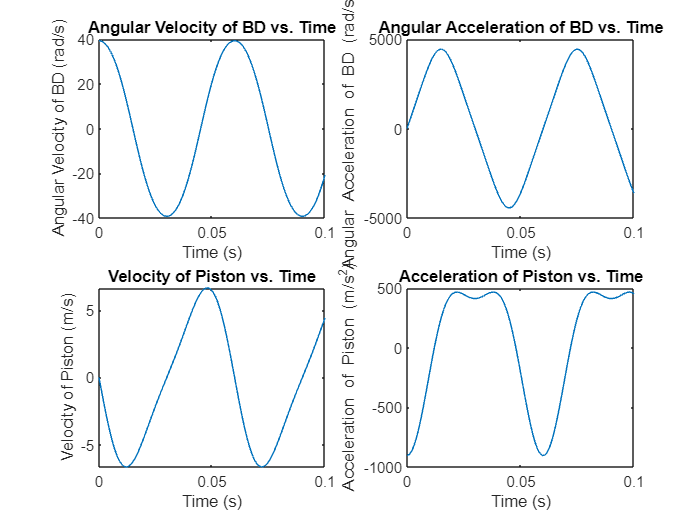

% Given data
l = 160 / 1000; % Length of BD (meters)
b = 60 / 1000;  % Crank length (meters)
n = l / b;      % Ratio of connecting rod to crank

% Angular velocity of crank AB (constant)
N = 1000; % RPM
w = 2 * pi * N / 60; % Angular velocity in radians per second

% Time vector (from 0 to 2 seconds, for example)
t = linspace(0, 0.1, 100); % Adjust the time range as needed

% Angular position (theta) as a function of time
theta = w * t;

% Angular velocity of BD (connecting rod) in terms of time
wBD = w * cos(theta) ./ sqrt(n^2 - sin(theta).^2);

% Angular acceleration of BD in terms of time
alphaBD = w^2 * (n^2 - 1) * sin(theta) ./ ((n^2 - sin(theta).^2).^(3/2));

% Plot results
subplot(2,2,1);
plot(t, wBD);
xlabel('Time (s)');
ylabel('Angular Velocity of BD (rad/s)');
title('Angular Velocity of BD vs. Time');

subplot(2,2,2);
plot(t, alphaBD);
xlabel('Time (s)');
ylabel('Angular Acceleration of BD (rad/s^2)');
title('Angular Acceleration of BD vs. Time');

% Velocity of piston P (in terms of time)
Vp = -1 * b * w * (sin(theta) + sin(2 * theta) / (2 * n));

% Acceleration of piston P (in terms of time)
ap = -1 * b * w^2 * (cos(theta) + cos(2 * theta) / n);

subplot(2,2,3);
plot(t, Vp);
xlabel('Time (s)');
ylabel('Velocity of Piston (m/s)');
title('Velocity of Piston vs. Time');

subplot(2,2,4);
plot(t, ap);
xlabel('Time (s)');
ylabel('Acceleration of Piston (m/s^2)');
title('Acceleration of Piston vs. Time');

Deriving the values for Phase l

%theta = 0
% Velocity of piston P (in terms of time)
Vp_theta0 = -1 * b * w * (sin(0) + sin(2 * 0) / (2 * n))

Vp_theta0 = 0



% Velocity of piston P (in terms of time)
Vp_theta90 = -1 * b * w * (sin(pi/2) + sin(2 * pi/2) / (2 * n))

Vp_theta90 = -6.2832



% Angular velocity of BD (connecting rod) in terms of time
wBD_theta0 = w * cos(0) ./ sqrt(n^2 - sin(0).^2)

wBD_theta0 = 39.2699


% Angular velocity of BD (connecting rod) in terms of time
wBD_theta90 = round(w * cos(pi/2) ./ sqrt(n^2 - sin(pi/2).^2))

wBD_theta90 = 0